syms x y
f=input("ingrese la funcion: ")

$$f = -\frac{y\,\left(\frac{y}{50}-1\right)}{50}$$


x0 = input("ingrese x inicial: ");
r = [x0 input("ingrese condicion inicial y(x0): ")]

r =          0    0.0200


xf = input("ingrese x final: ");
h = input("ingrese h: ");

Y(x0, r)

ans = 0.0200


for xi = x0+h:h:xf
    fn= subs(f,[x y],[xi-h Y(xi-h,r)]);
    fi= subs(f,[x y],[xi Y(xi-h,r)+h*fn]);
    yxi = Y(xi-h,r)+h*((fn+fi)/2)
    r = [r; [xi, vpa(yxi)]];
end

$$yxi = \frac{118316829371}{1525878906250}$$

$$yxi = 0.2999564682737895031514584235717$$

$$yxi = 1.1504283290837543811168982531613$$

$$yxi = 4.269481757594530938851758942895$$

$$yxi = 14.037453163742576185750541498778$$

$$yxi = 31.68334174074008098986061181018$$

$$yxi = 40.764439870796363794280190355617$$

$$yxi = 44.412150083804275010198006745206$$

$$yxi = 46.411386702541357977279431759322$$

Mostrar resultados

disp("Resultados finales:");

Resultados finales:


fprintf('y(%f): %f\n', xf,Y(xf,r));

y(720.000000): 46.411387


disp("Resultados real:");

Resultados real:


syms x y(x)
solucion = dsolve( diff(y,x) == subs(f, y,y(x)),y(x0)==Y(x0,r), x)

$$solucion = \frac{50}{{\mathrm{e}}^{\log\left(2499\right)-\frac{x}{50}}+1}$$

fprintf('Valor real y(%f): %f\n', xf,vpa(subs( solucion,x,xf )));

Valor real y(720.000000): 49.930451


r2 =[];
for i = 1:height(r)
    vreal= subs( solucion,x,r(i,1));
    r2 = [r2;r(i,1) r(i,2) vreal vpa(abs( (vreal-r(i,2))/vreal) )];
end
tablita=table(r2,'VariableNames',{'res'})

tablita = 10×1 table
      res  
    _______

    1×4 sym
    1×4 sym
    1×4 sym
    1×4 sym
    1×4 sym
    1×4 sym
    1×4 sym
    1×4 sym
    1×4 sym
    1×4 sym


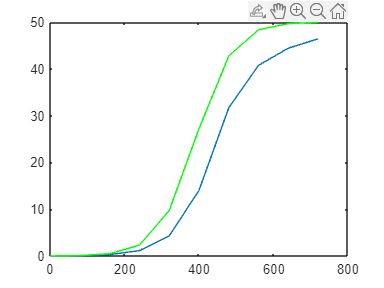

plot(tablita.res(:,1),tablita.res(:,2))
hold on
plot(tablita.res(:,1),tablita.res(:,3),'Color','green')
hold off

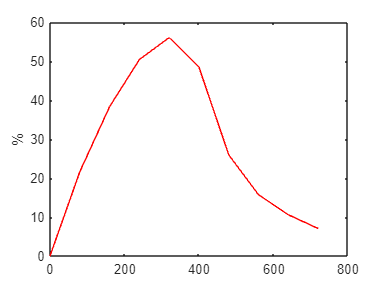

plot(tablita.res(:,1), tablita.res(:,4)*100, 'Color', 'red');

ylabel("%")

Tablar la funcion y

function imagen = Y(x, tabla)
    for c = 1:height(tabla)
        if(tabla(c,1) == x)
            imagen = tabla(c,2);
        end
    end
end